# Run the Simulation programatically:

## Overview:

As an alternative to opening the Simulink model and clicking on the RUN button, we can alos run a Simulink model programatically. Why ? - this is especially useful when:

- you want to do a parameter sweep, eg: run 1000's of simulations and varying parameters for each run

- you want to solve an optimization problem and teh Simulink model can be part of the "Cost Function"

## Good Resources:

- ` web(fullfile(docroot, 'simulink/examples/multiple-simulations-workflow-tips.html'))`

- ` web(fullfile(docroot, 'simulink/ug/optimize-estimate-and-sweep-block-parameter-values.html'))`

- ` web(fullfile(docroot, 'simulink/slref/simulink.modelworkspace.html'))`

## Configure the model - part 1:

Although we could use the **BASE workspace** for storing our model variables/parameters ...  a "good practice" is to NOT use it when you're running the model programatically - especially when you start doing multiple runs of your model (eg: parameter sweeps).

So? - So we'll configure the model to use the **MODEL workspace** rather than the common BASE workspace.

THE_MODEL = 'bh_a_spring_mass_model';
open_system(THE_MODEL);
hws = get_param(THE_MODEL,'modelworkspace');
hws.DataSource = 'MATLAB Code'

hws = Simulink.ModelWorkspace
    DataSource: 'MATLAB Code'
    MATLABCode: 'bh_smd_params'


hws.MATLABCode = 'bh_smd_params';

% now force the MATLAB code to run and to populate the MODEL's workspace
hws.reload

## Configure the model - part 2:

Specify some model parameters.  In particular I want to save the ROOT level output (ie the ORANGE block) to a variable called "*brads_yout*".

simIn= Simulink.SimulationInput(THE_MODEL);

% next configure the Model parameters
simIn = simIn.setModelParameter('SaveOutput',     'on');
simIn = simIn.setModelParameter('OutputSaveName', 'brads_yout');
simIn = simIn.setModelParameter('SaveFormat',     'Dataset');
simIn = simIn.setModelParameter('StopTime',       '10');

## do a damping ratio parameter sweep:

First, retrieve the m and k :

THE_M = getVariable(hws,'m');
THE_K = getVariable(hws,'k');

THE_WN = sqrt(THE_K/THE_M);

Now do the damping PARAMETER sweep 

damp_rat_list = (0.1:0.1:0.6);

X_MAT = [];
T     = [0:0.01:10]'  ;

for COUNT=1:length(damp_rat_list)
    
    damp_rat = damp_rat_list(COUNT);
    % calc damping
    THE_C = 2*damp_rat*THE_WN;
    % assign this value to the 'c' in the model workspace
    assignin(hws, 'c', THE_C);
    % run the sim
    simOut = sim( simIn );

    % extract the ssignal of interest
    t     = simOut.brads_yout{1}.Values.Time;
    x_pos = simOut.brads_yout{1}.Values.Data;
    
    % create a new interpolated results data set
    % - in case we usde a VARIABLE step solver
    
    x_pos_new = interp1(t,x_pos,T, 'pchip');
    
    % store result
    X_MAT(:,COUNT) = x_pos_new(:);
end

## Close the model - do NOT save any changes

tf_save_stuff = false;
close_system(THE_MODEL, tf_save_stuff)

## Visualize the results

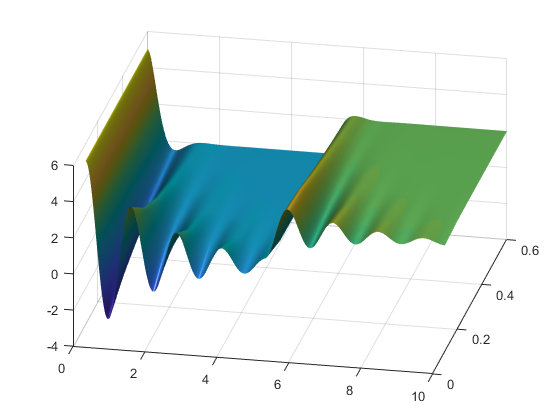

figure
[Tm, DRm] = meshgrid(T,damp_rat_list);
surf(Tm,DRm,X_MAT', 'EdgeColor', 'none')
%surf(Tm,DRm,X_MAT')
shading interp
camlight
lighting gouraud

view([11.70 37.20])